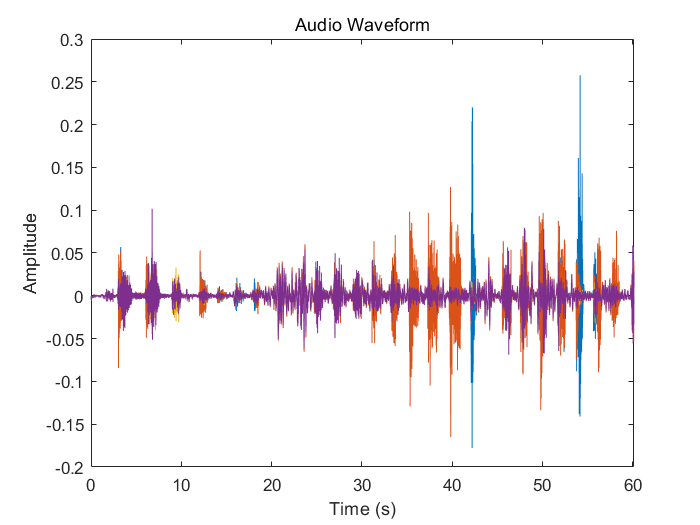

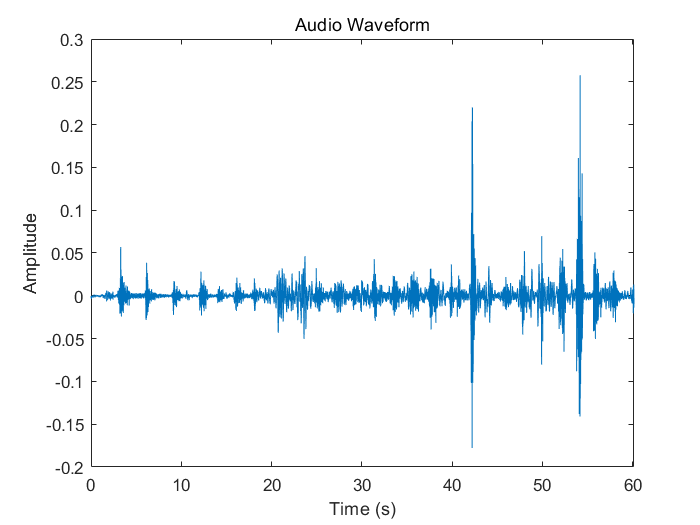

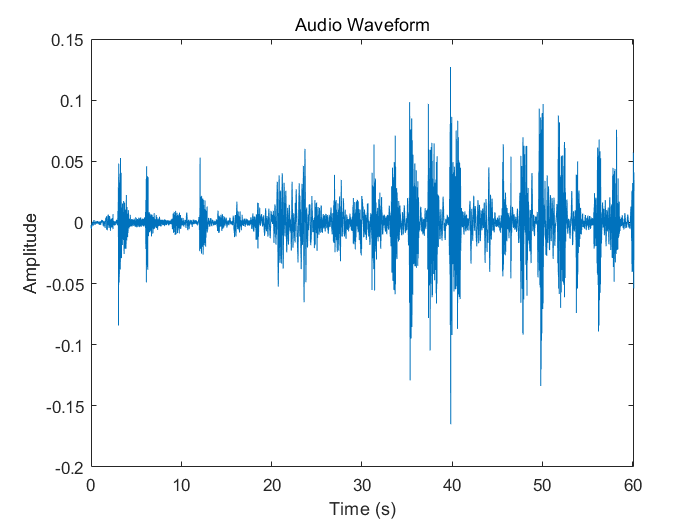

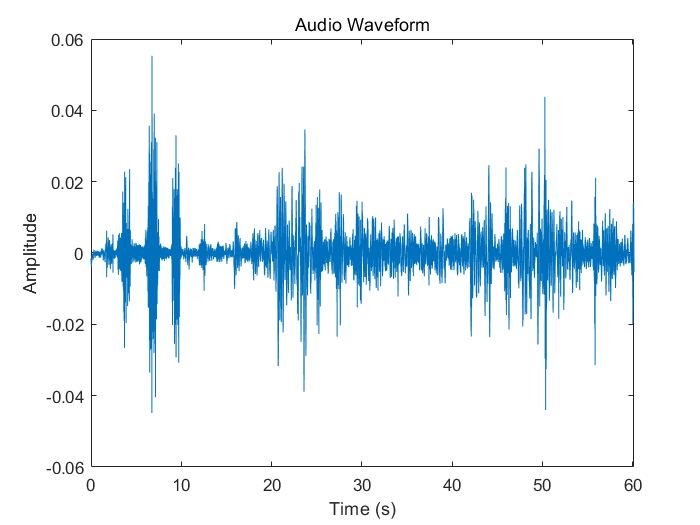

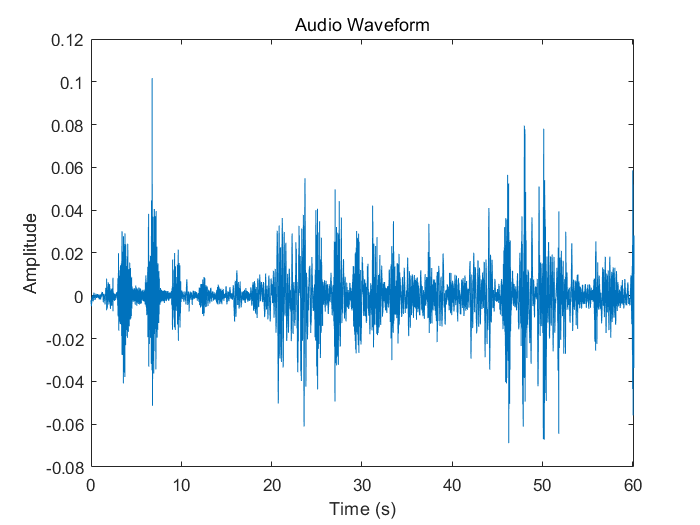

clear all

file='C:\Users\Desktop\dorm\audio12.wav';
% file1='E:\Sound2.wav';

data=timeDuration(file);

% timeDuration(file1)

ch1=data(:,1);
ch2=data(:,2);
ch3=data(:,3);
ch4=data(:,4);

function data=timeDuration(filename)

[data, fs] = audioread(filename);
duration = length(data) / fs;
t = linspace(0, duration, length(data));
figure
plot(t, data);
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Waveform');
xlim([0,duration]);
figure
plot(t, data(:,1));
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Waveform');
xlim([0,duration]);
figure
plot(t, data(:,2));
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Waveform');
xlim([0,duration]);
figure
plot(t, data(:,3));
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Waveform');
xlim([0,duration]);
figure
plot(t, data(:,4));
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Waveform');
xlim([0,duration]);
end